# BIV Whirlpool-Galaxie Processing

## Preprocessing

Setup

dark_frame_file = "darkframe.tiff";
background_file = "background_fit.tiff";
raw_files = dir("raw/*.tiff");

addpath('code');

Load darkframe, hotpixels and background

background = im2double(imread(background_file));

hot_pixels = im2double(imread(fullfile("raw/", raw_files(1).name)));
for k = 2:numel(raw_files)
    frame = im2double(imread(fullfile("raw/", raw_files(k).name)));
    hot_pixels = hot_pixels .* frame * 10;
end

save_image(hot_pixels, "hot_pixels.tif");

dark_frame = im2double(imread(dark_frame_file));

Calibrate raw images by subtracting darkframe and hotpixels - save them

n = numel(raw_files);

margin_from_edge = 20;

for k = 1:n
    name = raw_files(k).name;
    img = im2double(imread(fullfile("raw/", name)));
    img_calibrated = img - dark_frame - hot_pixels;
    img_calibrated(img_calibrated < 0) = 0; % Clip negatives

    cropped = circular_crop(img_calibrated, margin_from_edge); % Crop out the edges
    save_image(cropped, fullfile("calibrated_raw/", name));
end

## Stacking

Load Calibrated

calibrated_images = {};
n = numel(raw_files);
for k = 1:n
    name = raw_files(k).name;
    img = (imread(fullfile("calibrated_raw/", name)));
   
    calibrated_images{end+1} = img;
end


Reference image

reference = calibrated_images{1};

Align images to reference

aligned_images = cell(size(calibrated_images));
aligned_images{1} = reference;
h = waitbar(0, 'Aligning images...');

% Detect stars
points_fixed  = get_star_tracking_points(reference);

for k = 2:n
    moving_image = calibrated_images{k};
    
    % Detect stars
    points_moving = get_star_tracking_points(moving_image);

    [matched_points, points_moving] = match_points(points_fixed, points_moving);
    
    % Find transform
    tform = estimateGeometricTransform2D(points_moving, matched_points, 'similarity');
    
    % Warp image
    output_view = imref2d(size(reference));
    aligned = imwarp(moving_image, tform, "OutputView", output_view);
    
    aligned_images{k} = aligned;

    % Save aligned
    save_image(aligned, fullfile("aligned/", raw_files(k).name));

    waitbar(k/n, h, sprintf('Aligned %d of %d images', k, n));
end

close(h);

Stack images

stack_sum = zeros(size(reference), 'double');  % preallocate as double
n = numel(aligned_images);

for k = 1:n
    stack_sum = stack_sum + im2double(aligned_images{k});  % convert each frame to double
end

stack_mean = stack_sum / n;

Background Correction

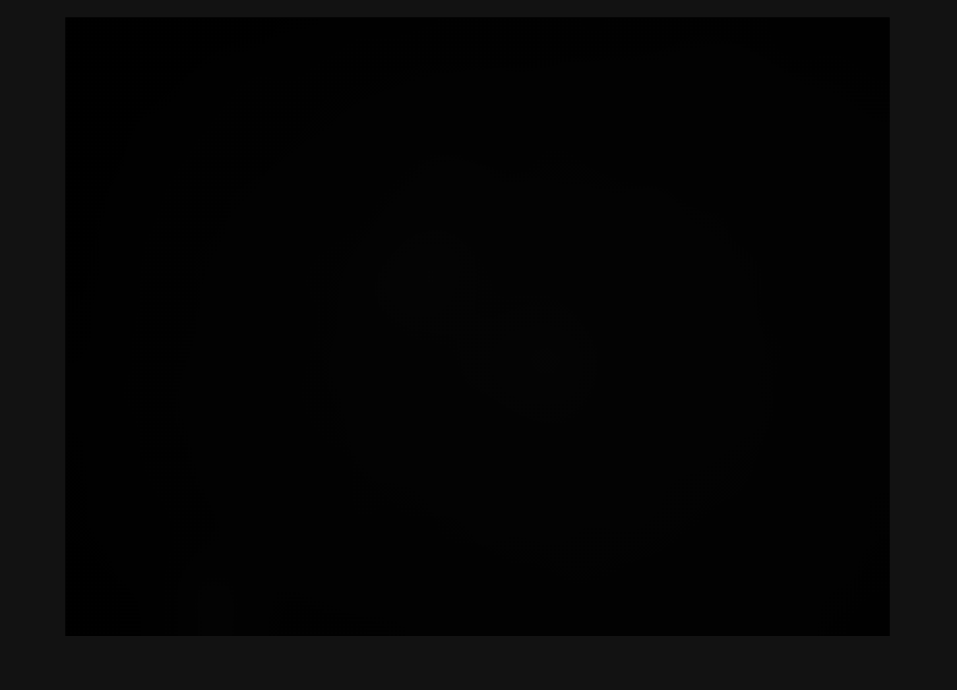

stack_mean_crop = crop_to_match(stack_mean, background);
scaled_bg = background *.02;
imshow(scaled_bg);

img_clean = stack_mean_crop - scaled_bg;
img_clean(img_clean<0) = 0;

img_clean = stack_mean;

Save

save_image(img_clean, "output.tif");

Display

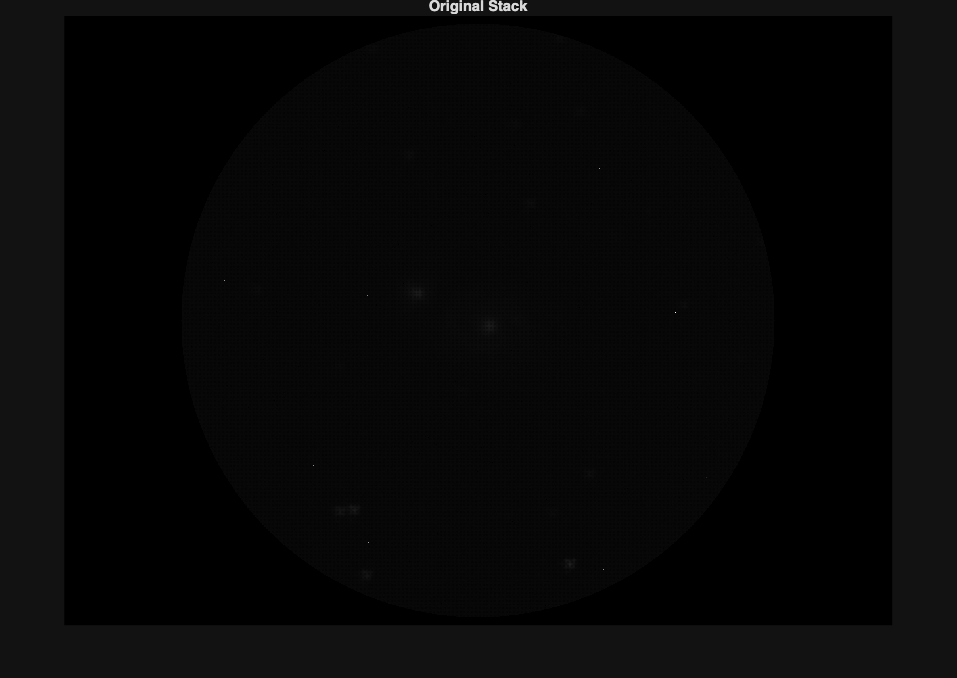

figure; imshow(img_clean, []); title('Original Stack');

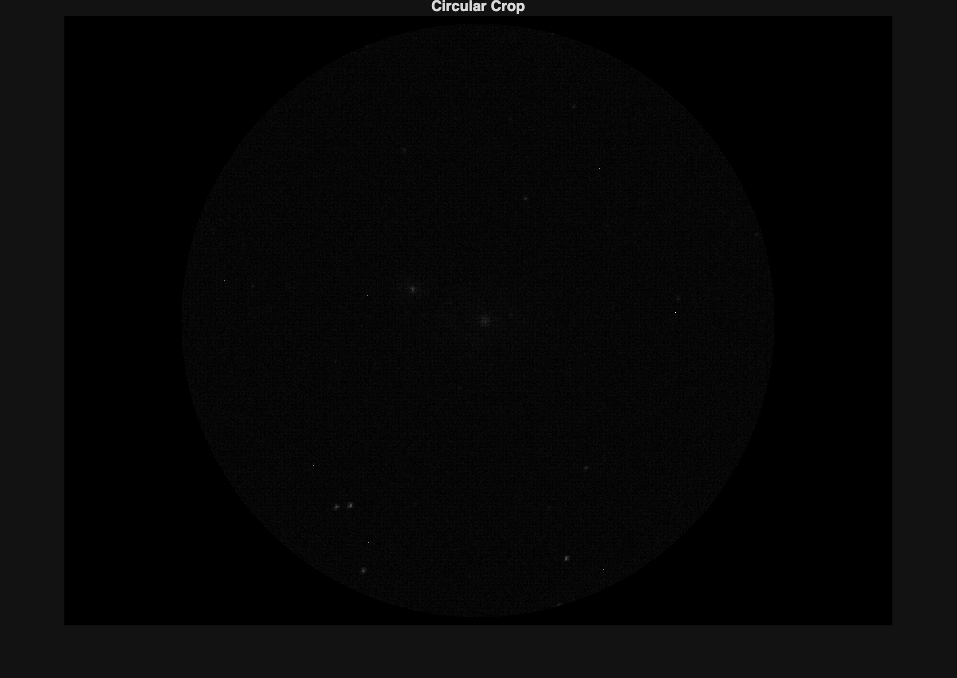

figure; imshow(cropped, []); title('Circular Crop');

PostProcess

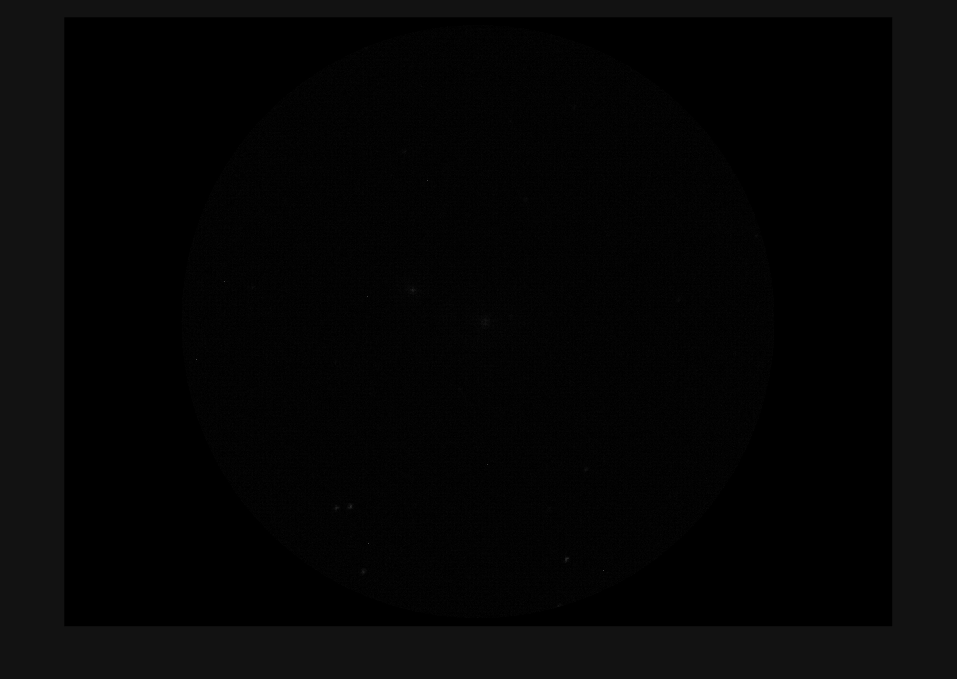

img_stretch = cropped;%enhance_contrast(cropped);

imshow(img_stretch)

save_image(img_stretch, "output.tif");